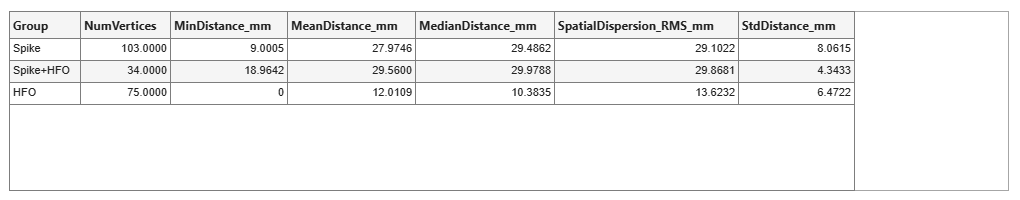

% Tabla a exportar
T = ResultsTable;

% Comprobar que realmente es una tabla
if ~istable(T)
    error('ResultsTable no es una table de MATLAB.');
end

% Tamaño automático de la ventana según filas y columnas
[nRows, nCols] = size(T);
colWidth    = 140;   % ancho aproximado por columna
rowHeight   = 22;    % alto por fila
margin      = 20;

figW = max(700, min(3000, nCols * colWidth + 2*margin));
figH = max(200, min(4000, (nRows + 1) * rowHeight + 2*margin));

% Crear ventana UI
f = uifigure('Color','w', 'Position',[100 100 figW figH]);

% Nombres de fila
if isempty(T.Properties.RowNames)
    rowNames = {};
else
    rowNames = T.Properties.RowNames;
end

% Crear tabla visual
uit = uitable(f, ...
    'Data', table2cell(T), ...
    'ColumnName', T.Properties.VariableNames, ...
    'RowName', rowNames, ...
    'FontSize', 11, ...
    'Position', [10 10 figW-20 figH-20]);

% Ajustar ancho de columnas automáticamente
uit.ColumnWidth = 'fit';


% Forzar renderizado
drawnow;

% Guardar como imagen
exportapp(f, 'ResultsTable.png');

% Guardar copia en la ruta solicitada (asegurar que la carpeta existe)
destDir = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO';
if ~isfolder(destDir)
    mkdir(destDir);
end

% Ruta completa de destino
destFile = fullfile(destDir, 'ResultsTable.png');

% Copiar el archivo exportado (si exportapp ya creó ResultsTable.png)
if exist('ResultsTable.png','file')
    % Intentar mover/copy el archivo generado por exportapp
    try
        copyfile('ResultsTable.png', destFile);
    catch
        warning('No se pudo copiar ResultsTable.png a la carpeta destino.');
    end
else
    % Si exportapp no creó el archivo en el directorio actual, export directamente allí
    try
        exportapp(f, destFile);
    catch ME
        warning('No se pudo exportar la imagen directamente a la ruta destino: %s', ME.message);
    end
end
% Cerrar ventana si quieres
% close(f)